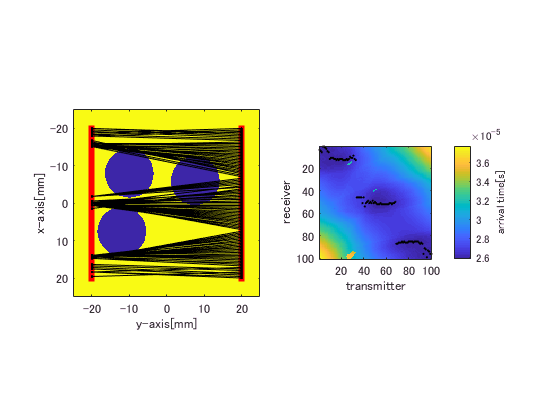

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave');
myfilename = sprintf('2018_04_26_Group1ERate5IRate02Num3-2');
cd(myfilename);
load('kgrid.mat')
i = 16;

figure;
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_04_26_randomScatter')
myfilename = sprintf('Group1ERate%dIRate02Num3-2', i);
load(myfilename);
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_04_27_analyzeLipidModel')
myfilename = sprintf('2018_04_27_TOFdata_Group1ERate%dIRate02Num3-2',i);
load(myfilename)

param = makeParam( 0.125,0.125,400,400,0 );
param.source.point_map = cast(linspace(1,100,100),'int8');
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
sensor.mask=t_pos;

Min = zeros(1,100);
ind = zeros(1,100);
for i = 1:100
    [Min(1,i),ind(1,i)]= min(tof_data(101:end,i));
    ind(1,i) = ind(1,i)+100;
end

subplot(1,2,1);
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
axis equal
axis tight
hold on
scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
xlabel('y-axis[mm]')
ylabel('x-axis[mm]')

hold on
for i = 1:length(ind)
    plot([t_pos(2,i)*1000;t_pos(2,ind(i))*1000],[t_pos(1,i)*1000;t_pos(1,ind(i))*1000],'.-k','LineWidth',0.01);
end
hold off

subplot(1,2,2);

imagesc(1:100,1:100,tof_data(101:end,:));
hold on
scatter(1:100,ind(1,1:100)-100,3,'filled','k','o')
xlabel('transmitter')
ylabel('receiver')
colorbar;
c = colorbar;
c.Label.String = 'arrival time[s]';
axis tight
axis equal

上の結果をみると，EMCLに影響されない区間では，正対向する素子同士が最速ペアになるはず．

しかしながら，ところどころクロスしてしまっている．この原因がtof-pickerの原因なのか，シミュレーションによるもの

なのかを明確にする．

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_02_28_-kwave\2018_04_26_Group1ERate16IRate02Num3-2')
load('rfdata.mat')

送信素子96で上のような現象が起こっている．一度rfdataを見てみる．

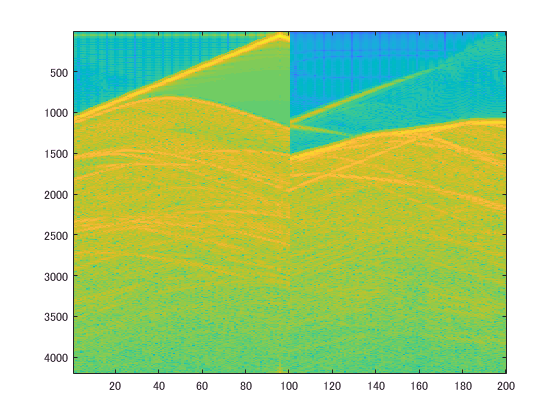

figure;
imagesc(20*log10(abs(rfdata(:,:,96))));

ind_96 = ind(1,96);
tof_96_199 = tof_data(199,96);
tof_96_196 = tof_data(196,96);

tof_mapの操作自体にはミスはないと思われる．実際に２つ(受信素子96,99)のrfdataを並べて比べてみる．

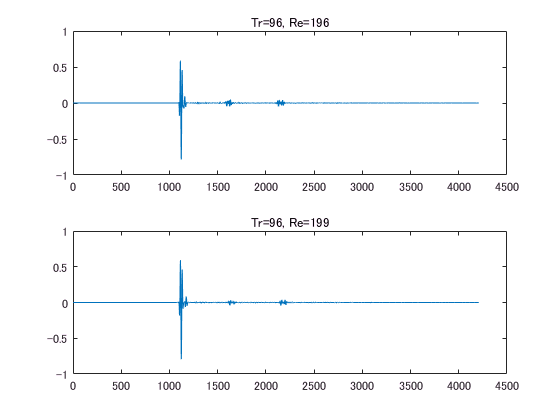

figure;
subplot(2,1,1);
plot(rfdata(:,196,96));
title('Tr=96, Re=196')
subplot(2,1,2);
plot(rfdata(:,199,96));
title('Tr=96, Re=199')

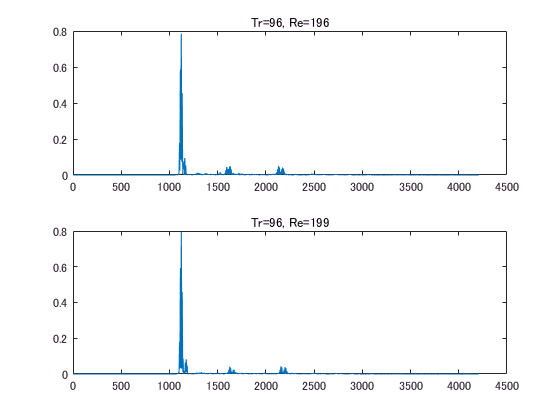


figure;
subplot(2,1,1);
plot(abs(rfdata(:,196,96)));
title('Tr=96, Re=196')
subplot(2,1,2);
plot(abs(rfdata(:,199,96)));
title('Tr=96, Re=199')

ほとんど形が同じ．波形最大値の位置がわずかに異なる．エネルギーはやはりTr=96, Re=196の方が多い

計算誤差によるものが大きいと考えられる．

１．グリッドを細かくして精度を上げて改善させる方針

２．問題点を明らかにしてfuture-workとして示す．